clc;
clear;
close all;

#### Cálculos de derivadas

% Definición de los parámetros del sistema
M = 1.096; m = 0.109; L = 0.5; g = 9.81; F = 1; mu = 0; b=0.1; I=0.0034;

%Punto de operación
x1=0; x2=0; x3=0; x4=0;

%valores repetidos

u1=F+(M+m)*g*tan(x3)-b*x2-m*L*((x4)^2)*sin(x3);

du1=(M+m)*g*((sec(x3))^2)-m*L*((x4)^2)*cos(x3);

u2=F*cos(x3)+(M+m)*g*sin(x3)-b*x2*cos(x3)-m*L*((x4)^2)*sin(x3)*cos(x3);

du2=-F*sin(x3)+(M+m)*g*cos(x3)+b*x2*sin(x3)-m*L*((x4)^2)*cos(2*x3);

v=((M+m)*(I+m*L^2)-((m*L)^2)*(((cos(x3))^2)));

dv=((M*L)^2)*sin(2*x3);
%Para f1
df1dx1=0;  df1dx2=1; df1dx3=0; df1dx4=0; df1dF=0;

%Para f2
df2dx1=0;

df2dx2=-((I+m*L^2)*(b))/v;

df2dx3=(((I+m*L^2)*(du1*v-dv*u1))/(v^2))-g*((sec(x3))^2);

df2dx4=((-2)*(I+m*L^2)*(m*L*x4*sin(x3)))/(v);

df2dF=(I+m*L^2)/(v);

%Para f3
df3dx1=0; df3dx2=0; df3dx3=0; df3dx4=1; df3dF=0;

%Para f4
df4dx1=0;

df4dx2=(-b*m*L*cos(x3))/(v);

df4dx3=((m*L)*(du2*v-dv*u2))/(v^2);

df4dx4=(-2*((m*L)^2)*x4*sin(x3)*cos(x3))/(v);

df4dF=(m*L*cos(x3))/(v);


#### Aquí se definen las matrices del MVE

%Matriz A
A=[df1dx1, df1dx2, df1dx3, df1dx4;
   df2dx1, df2dx2, df2dx3, df2dx4;
   df3dx1, df3dx2, df3dx3, df3dx4;
   df4dx1, df4dx2, df4dx3, df4dx4]

A =          0    1.0000         0         0
         0   -0.0902    0.8579         0
         0         0         0    1.0000
         0   -0.1605   18.9691         0



%Matriz B
B=[df1dF;
   df2dF;
   df3dF;
   df4dF]

B =          0
    0.9025
         0
    1.6047



%Matriz C
C=[1,0,0,0;
   0,0,1,0]

C =      1     0     0     0
     0     0     1     0



%Matriz D
D=[0;
   0]

D =      0
     0


%Matriz identidad
I=[1,0,0,0;
   0,1,0,0;
   0,0,1,0;
   0,0,0,1];

%variable compleja
s=tf('s');

%(sI-A)
a=(s*I-A);

%Matriz de funciones de transferencia
G=C*inv(a)*B+D;

%Primer función de transferencia (x)
G1=G(1,1)

G1 =
 
            0.9025 s^6 + 0.08144 s^5 - 32.86 s^4 - 2.841 s^3 + 298.6 s^2 + 24.78 s - 5.06e-16
  ------------------------------------------------------------------------------------------------------
  s^8 + 0.1805 s^7 - 37.93 s^6 - 6.572 s^5 + 359.5 s^4 + 59.72 s^3 + 2.478 s^2 + 1.522e-17 s - 9.671e-34
 
Continuous-time transfer function.



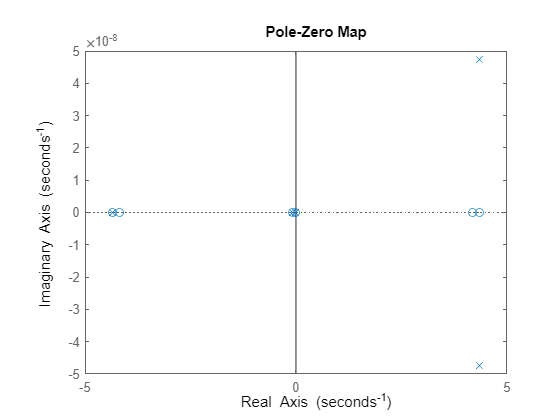

pzmap(G1)

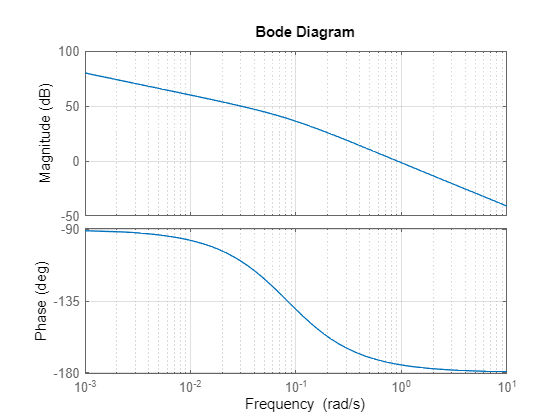

bode(G1)
grid on


%Segunda función de transferencia (theta)
G2=G(2,1)

G2 =
 
  2.71e-15 s^5 + 1.605 s^4 + 0.1448 s^3 - 30.44 s^2 - 2.526 s + 5.274e-16
  -----------------------------------------------------------------------
  s^6 + 0.1805 s^5 - 37.93 s^4 - 6.572 s^3 + 359.5 s^2 + 59.72 s + 2.478
 
Continuous-time transfer function.



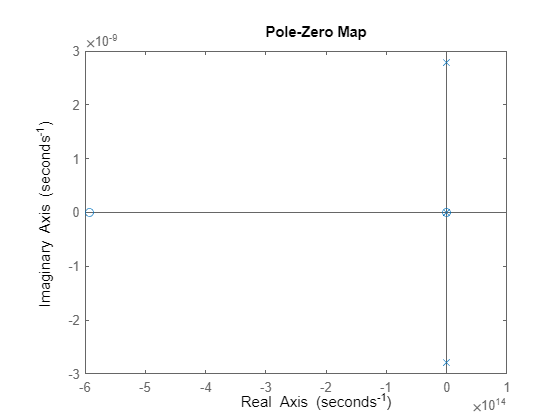

pzmap(G2)

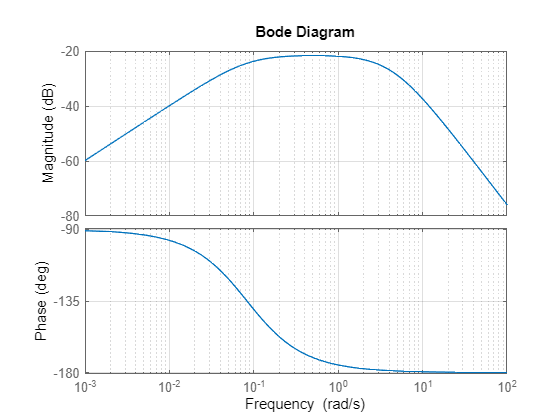

bode(G2)
grid on